% ----------------------------------------------------------------------
%   Screw Linear Interpolation (sclerp)
%    20210108  y.yoshimura
%    Inputs:
%   Outputs:
%   related function files:
%   note:
%   cf:
%   revisions;
%
%   (c) 2021 yasuhiro yoshimura
%----------------------------------------------------------------------

clc
clear
close all


## load object

sat = readSC('oneWeb.obj');

number of vertices:
   654

number of faces:
        1296



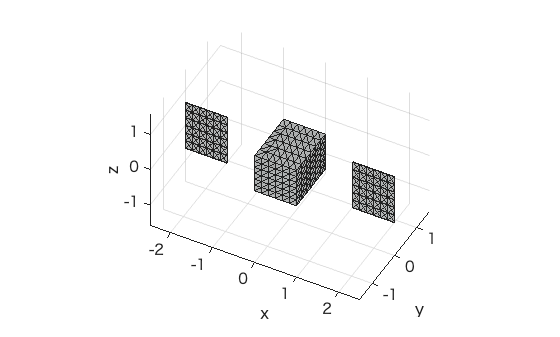


showSC(sat)

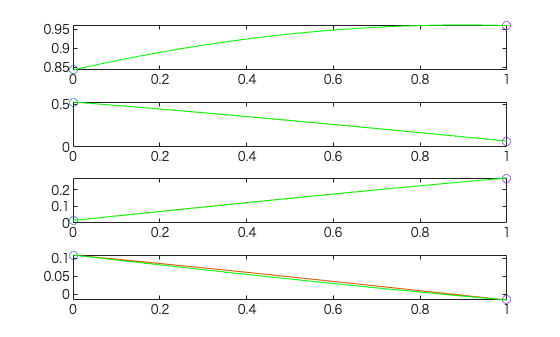


%% c1 sclerp
dt = 0.01;
t = 0:dt:1;
ri1 = [1.0 0.5 2.0]; % translation
v1 = [5 0.5 2];
dq1_r = [0.842819253762211   0.526666432942754   0.015418879683130   0.109728902520637];
w1 = [0 0.5 1];
dq1_d = 0.5 .* qMult(4, 0, [ri1 0], dq1_r);
dq1 = [dq1_r dq1_d];

ri2 = [6 1 4];
v2 = [5 0.5 2];
dq2_r = [0.959831097755649   0.069304089509363   0.271389093408073  -0.016406307856286];
w2 = [ -0.098880783535083   0.480829792865113 1.004876813023622];
dq2_d = 0.5 .* qMult(4, 0, [ri2 0], dq2_r);
dq2 = [dq2_r dq2_d];

ri3 = [11 1.5 6];
v3 = [5 0.5 2];
dq3_r = [0.790463505310802  -0.424986432062897   0.430644815240163  -0.095388796201134];
w3 = [-0.190966345198502   0.424109598955283 1.018070795671143];
dq3_d = 0.5 .* qMult(4, 0, [ri3 0], dq3_r);
dq3 = [dq3_r dq3_d];

dqt1 = sclerp(t, 4, dq1, dq2);
dqt2 = sclerp(t, 4, dq2, dq3);

% control dual quaternions
dtp = 1;
tmp = [dtp/6.*w1, dtp/6.*v1];
eTheta = 2 .* norm(tmp(1:3));
eAxis = tmp(1:3) ./ (eTheta/2);
dqtmp_r = [eAxis.*sin(eTheta/2) cos(eTheta/2)];
dqtmp_d = 0.5 .* qMult(4, 0, [tmp(4:6) 0], dqtmp_r);
dq_tmp = [dqtmp_r dqtmp_d];
dqa = dqMult(4, 0, dq1, dq_tmp);

tmp = [-dtp/6.*w2, -dtp/6.*v2];
eTheta = 2 .* norm(tmp(1:3));
eAxis = tmp(1:3) ./ (eTheta/2);
dqtmp_r = [eAxis.*sin(eTheta/2) cos(eTheta/2)];
dqtmp_d = 0.5 .* qMult(4, 0, [tmp(4:6) 0], dqtmp_r);
dq_tmp = [dqtmp_r dqtmp_d];
dqb = dqMult(4, 0, dq2, dq_tmp);

% c1 sclerp
dq_c1 = zeros(length(t), 8);
for i = 1:length(t)
    time = t(i);
    dqtmp1 = sclerp(time, 4, sclerp(time, 4, dq1, dqa), sclerp(time, 4, dqa, dqb));
    dqtmp2 = sclerp(time, 4, sclerp(time, 4, dqa, dqb), sclerp(time, 4, dqb, dq2));
    
    dq_c1(i,:) = sclerp(time, 4, dqtmp1, dqtmp2);
end

% q2 → q3
tmp = [dtp/6.*w2, dtp/6.*v2];
eTheta = 2 .* norm(tmp(1:3));
eAxis = tmp(1:3) ./ (eTheta/2);
dqtmp_r = [eAxis.*sin(eTheta/2) cos(eTheta/2)];
dqtmp_d = 0.5 .* qMult(4, 0, [tmp(4:6) 0], dqtmp_r);
dq_tmp = [dqtmp_r dqtmp_d];
dqa = dqMult(4, 0, dq2, dq_tmp);

tmp = [-dtp/6.*w3, -dtp/6.*v3];
eTheta = 2 .* norm(tmp(1:3));
eAxis = tmp(1:3) ./ (eTheta/2);
dqtmp_r = [eAxis.*sin(eTheta/2) cos(eTheta/2)];
dqtmp_d = 0.5 .* qMult(4, 0, [tmp(4:6) 0], dqtmp_r);
dq_tmp = [dqtmp_r dqtmp_d];
dqb = dqMult(4, 0, dq3, dq_tmp);

% c1 sclerp
dq_c2 = zeros(length(t), 8);
for i = 1:length(t)
    time = t(i);
    dqtmp1 = sclerp(time, 4, sclerp(time, 4, dq2, dqa), sclerp(time, 4, dqa, dqb));
    dqtmp2 = sclerp(time, 4, sclerp(time, 4, dqa, dqb), sclerp(time, 4, dqb, dq3));
    
    dq_c2(i,:) = sclerp(time, 4, dqtmp1, dqtmp2);
end

figure % real part
tiledlayout(4,1);
nexttile
plot(t(1), dq1(1), 'o');
hold on
plot(t, dqt1(:,1));
plot(t, dq_c1(:,1),'g');
plot(t(end), dq2(1), 'o');

nexttile
plot(t(1), dq1(2), 'o');
hold on
plot(t, dqt1(:,2));
plot(t, dq_c1(:,2),'g');
plot(t(end), dq2(2), 'o');

nexttile
plot(t(1), dq1(3), 'o');
hold on
plot(t, dqt1(:,3));
plot(t, dq_c1(:,3),'g');
plot(t(end), dq2(3), 'o');

nexttile
plot(t(1), dq1(4), 'o');
hold on
plot(t, dqt1(:,4));
plot(t, dq_c1(:,4),'g');
plot(t(end), dq2(4), 'o');

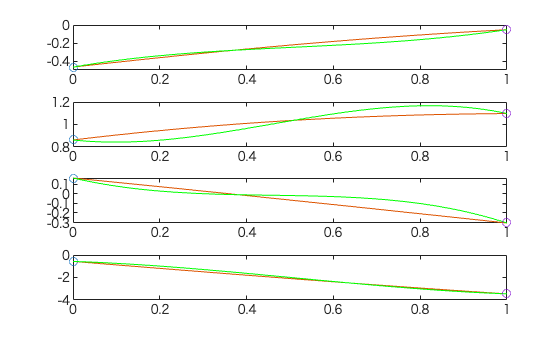


figure % dual part
tiledlayout(4,1);
nexttile
plot(t(1), dq1(5), 'o');
hold on
plot(t, dqt1(:,5));
plot(t, dq_c1(:,5),'g');
plot(t(end), dq2(5), 'o');

nexttile
plot(t(1), dq1(6), 'o');
hold on
plot(t, dqt1(:,6));
plot(t, dq_c1(:,6),'g');
plot(t(end), dq2(6), 'o');

nexttile
plot(t(1), dq1(7), 'o');
hold on
plot(t, dqt1(:,7));
plot(t, dq_c1(:,7),'g');
plot(t(end), dq2(7), 'o');

nexttile
plot(t(1), dq1(8), 'o');
hold on
plot(t, dqt1(:,8));
plot(t, dq_c1(:,8),'g');
plot(t(end), dq2(8), 'o');

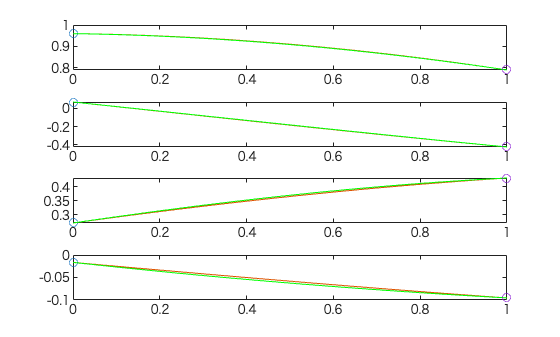


% q2 → q3
figure % real part
tiledlayout(4,1);
nexttile
plot(t(1), dq2(1), 'o');
hold on
plot(t, dqt2(:,1));
plot(t, dq_c2(:,1),'g');
plot(t(end), dq3(1), 'o');

nexttile
plot(t(1), dq2(2), 'o');
hold on
plot(t, dqt2(:,2));
plot(t, dq_c2(:,2),'g');
plot(t(end), dq3(2), 'o');

nexttile
plot(t(1), dq2(3), 'o');
hold on
plot(t, dqt2(:,3));
plot(t, dq_c2(:,3),'g');
plot(t(end), dq3(3), 'o');

nexttile
plot(t(1), dq2(4), 'o');
hold on
plot(t, dqt2(:,4));
plot(t, dq_c2(:,4),'g');
plot(t(end), dq3(4), 'o');

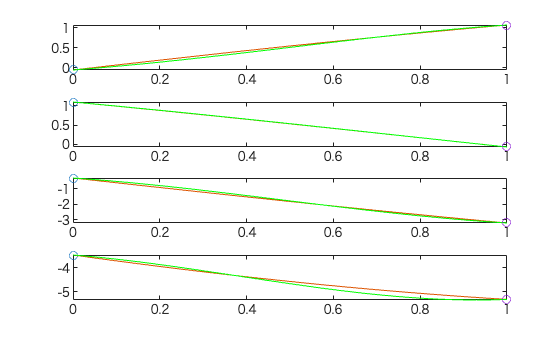


figure % dual part
tiledlayout(4,1);
nexttile
plot(t(1), dq2(5), 'o');
hold on
plot(t, dqt2(:,5));
plot(t, dq_c2(:,5),'g');
plot(t(end), dq3(5), 'o');

nexttile
plot(t(1), dq2(6), 'o');
hold on
plot(t, dqt2(:,6));
plot(t, dq_c2(:,6),'g');
plot(t(end), dq3(6), 'o');

nexttile
plot(t(1), dq2(7), 'o');
hold on
plot(t, dqt2(:,7));
plot(t, dq_c2(:,7),'g');
plot(t(end), dq3(7), 'o');

nexttile
plot(t(1), dq2(8), 'o');
hold on
plot(t, dqt2(:,8));
plot(t, dq_c2(:,8),'g');
plot(t(end), dq3(8), 'o');

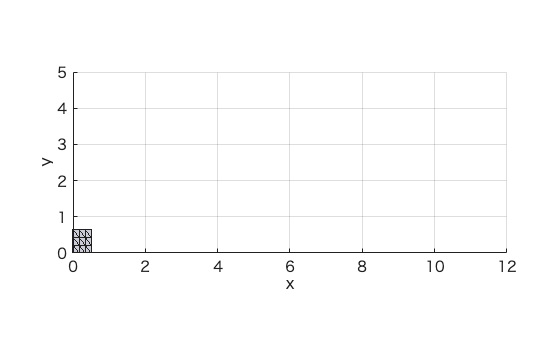


%% satellite pose
figure
axis equal
grid on
xlabel('x'), ylabel('y'), zlabel('z')
xlim([0 12]), ylim([0 5]), zlim([0 8])
h = patch('Faces',sat.faces,'Vertices', sat.vertices, 'facecolor', [0.0 0 0.2]);
alpha(0.2);
hold on

% target pose
dq_tmp = kron(ones(length(sat.vertices),1), dq2);
ri = 2 * qMult(4, 0, dq2(1,5:8), qInv(4,dq2(1,1:4)))

ri =    5.999999999999998   1.000000000000000   3.999999999999999  -0.000000000000000


newVertices = dqRotation(4, sat.vertices, dqInv(4,dq_tmp));

関数または変数 'dqRotation' が認識されません。

newVertices = newVertices + kron(ones(size(sat.vertices,1),1), ri(:,1:3));
patch('Faces',sat.faces,'Vertices', newVertices, 'facecolor', [0.5 0.0 0]);
alpha(0.2);

dq_tmp = kron(ones(length(sat.vertices),1), dq3);
ri = 2 * qMult(4, 0, dq3(1,5:8), qInv(4,dq3(1,1:4)))
newVertices = dqRotation(4, sat.vertices, dqInv(4,dq_tmp));
newVertices = newVertices + kron(ones(size(sat.vertices,1),1), ri(:,1:3));
patch('Faces',sat.faces,'Vertices', newVertices, 'facecolor', [0.0 0.5 0.0]);
alpha(0.2);
view([64 15])

for i = 1:length(dqt1)
    dq_tmp = kron(ones(length(sat.vertices),1), dqt1(i,:));
    ri = 2 * qMult(4, 0, dq_c1(i,5:8), qInv(4,dq_c1(i,1:4)));
    newVertices = dqRotation(4, sat.vertices, dqInv(4,dq_tmp));
    newVertices = newVertices + kron(ones(size(sat.vertices,1),1), ri(:,1:3));
    set(h, 'Vertices', newVertices, 'facecolor', [0 0 0.2]);
    drawnow
    pause(0.05)
end

for i = 1:length(dqt2)
    dq_tmp = kron(ones(length(sat.vertices),1), dqt2(i,:));
    ri = 2 * qMult(4, 0, dq_c2(i,5:8), qInv(4,dq_c2(i,1:4)));
    newVertices = dqRotation(4, sat.vertices, dqInv(4,dq_tmp));
    newVertices = newVertices + kron(ones(size(sat.vertices,1),1), ri(:,1:3));
    set(h, 'Vertices', newVertices, 'facecolor', [0 0 0.2]);
    drawnow
    pause(0.05)
end
%%% ↑ vector rotationなので qInvを使っている．
